clc;
clear;
Tuning2 = load("Data/M6M5ID_Test2_actuation_compensated.mat");
Tuning2 = Tuning2.data;

% Search for testing times via force plate z readings:
FPz = Tuning2{3}.Values;

Start_times = [];
End_times = [];
valid = false;
for i =1:length(FPz.Data)
    if valid
        if FPz.Data(i)>-5
            End_times = [End_times, FPz.Time(i)-2]; % Chop off the robot being picked up
            valid = false;
        end    
    else
        if FPz.Data(i)<-30
            Start_times = [Start_times, FPz.Time(i)+2];% Chop off the robot being put down
            valid = true;
        end
    end
end
% End_times(5) = End_times(5); % Strange artifact at the end of final sample - something went wring with lifting off the force plate.


Test_time = 0;
for i = 1:length(Start_times)
 Test_time = Test_time + End_times(i) - Start_times(i);
end


% Torques calculated via force plate forces using the jacobian, 
FPy = [];
FPz = [];
MRq = [];
MLq = [];
MRt_read = [];
MLt_read = [];
MRt_cmd = [];
MLt_cmd = [];
ts = 1000;
Start_times =int32(Start_times*ts);
End_times = int32(End_times*ts);



% Resamples
MR_q_resample = resample(Tuning2{5}.Values.q, Tuning2{1}.Values.Time);
ML_q_resample = resample(Tuning2{6}.Values.q, Tuning2{1}.Values.Time);
MR_t_resample = resample(Tuning2{5}.Values.t, Tuning2{1}.Values.Time);
ML_t_resample = resample(Tuning2{6}.Values.t, Tuning2{1}.Values.Time);
MR_t_cmd_resample = resample(Tuning2{9}.Values.tff, Tuning2{1}.Values.Time);
ML_t_cmd_resample = resample(Tuning2{8}.Values.tff, Tuning2{1}.Values.Time);
for i = 1:length(Start_times)
    % Force plate
    FPy = [FPy; Tuning2{2}.Values.Data(Start_times(i): End_times(i))];
    FPz = [FPz; Tuning2{3}.Values.Data(Start_times(i): End_times(i))];
    % Motor angles
    
    MRq = [MRq; MR_q_resample.Data(Start_times(i): End_times(i))];
    MLq = [MLq; ML_q_resample.Data(Start_times(i): End_times(i))];

    % Motor torques (cmd)
    
    MRt_cmd = [MRt_cmd; MR_t_cmd_resample.Data(Start_times(i): End_times(i))]; 
    MLt_cmd = [MLt_cmd; ML_t_cmd_resample.Data(Start_times(i): End_times(i))];
    
    % Motor torques (read)
   
    MRt_read = [MRt_read; MR_t_resample.Data(Start_times(i): End_times(i))];
    MLt_read = [MLt_read; ML_t_resample.Data(Start_times(i): End_times(i))];

end
clear MR_q_resample ML_q_resample MR_t_resample ML_t_resample MR_t_cmd_resample ML_t_cmd_resample


## Transfer Motor torques into forces

% From the side of forces:

Fy_read = [];
Fz_read = [];
FP_tl = [];
FP_tr = [];
[J11, J12, J21, J22] = BalekaJacobianXY(MLq, MRq);
for i = 1:length(FPz)
    Jxy = [J11(i), J12(i); J21(i), J22(i)];
    JTxy = Jxy';

    F_read = JTxy\[MLt_read(i)*9*0.198; MRt_read(i)*9*0.198];
    Fy_read = [Fy_read; F_read(1)];
    Fz_read = [Fz_read; F_read(2)];
end
clear F_cmd F_read i J11 J12 J22 J21 times ts JTxy Jxy


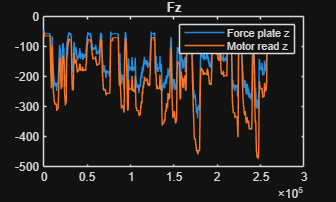

% forces:
plot(FPz)
hold on
plot(Fz_read)
legend('Force plate z', 'Motor read z');
title('Fz')
hold off


errFzRead = mean((Fz_read - FPz).^2)

errFzRead = 4.5286e+03


plot(FPy)
hold on
plot(Fy_read)
legend('Force plate y','Force plate Horizontal', 'Motor read Fy');

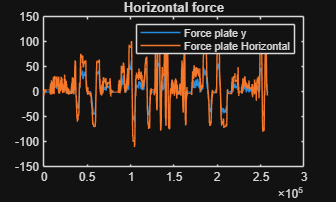

title('Horizontal force')
hold off

errFxyRead = mean((Fy_read - FPy).^2)

errFxyRead = 349.6452

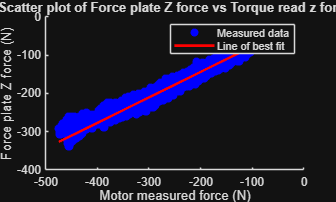

% Z force

[coeff, Sr] = polyfit(Fz_read, FPz, 1);
xFit = linspace(min(Fz_read), max(Fz_read), 1000);
yFit = polyval(coeff, xFit);

scatter(Fz_read, FPz, 'b','filled')
hold on
plot(xFit, yFit, 'r-', LineWidth=2)
title("Scatter plot of Force plate Z force vs Torque read z force");
ylabel("Force plate Z force (N)");
xlabel("Motor measured force (N)");
legend("Measured data", "Line of best fit")
hold off

m1 = coeff(1)

m1 = 0.6663

c1 = coeff(2)

c1 = -10.6614

R1 = Sr.rsquared

R1 = 0.9848

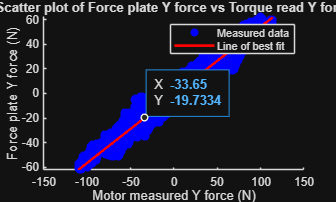

%where line of best fit is y=mx +c

% Y force
[coeff, Sr] = polyfit(Fy_read, FPy, 1);
xFit = linspace(min(Fy_read), max(Fy_read), 1000);
yFit = polyval(coeff, xFit);

scatter(Fy_read, FPy, 'b','filled')
hold on
plot(xFit, yFit, 'r-', LineWidth=2)
title("Scatter plot of Force plate Y force vs Torque read Y force");
ylabel("Force plate Y force (N)");
xlabel("Motor measured Y force (N)");
legend("Measured data", "Line of best fit")
hold off

m2 = coeff(1)

m2 = 0.5543

c2 = coeff(2)

c2 = -1.0796

R2 = Sr.rsquared

R2 = 0.9651

Rsq = corrcoef(FPy, Fy_read).^2

Rsq =     1.0000    0.9651
    0.9651    1.0000


%where line of best fit is y=mx +c